# optimize event mining 

1.remove duplicate 

Events with same K and starting time were removed expect the one with highest M. 

load('em_arena_th0.5.mat')
close all
p=6;m=1;
max(em{1,1}.ne{p,m})

ans = 1924

subplot(2,1,1)
plot(em{1,1}.ne{p,m});hold on 
plot(find(em{2,1}.timefilter{p,m}),em{2,1}.ne{p,m});
em=rem_dup_em(em);
max(em{1,1}.ne{p,m})

ans = 1824

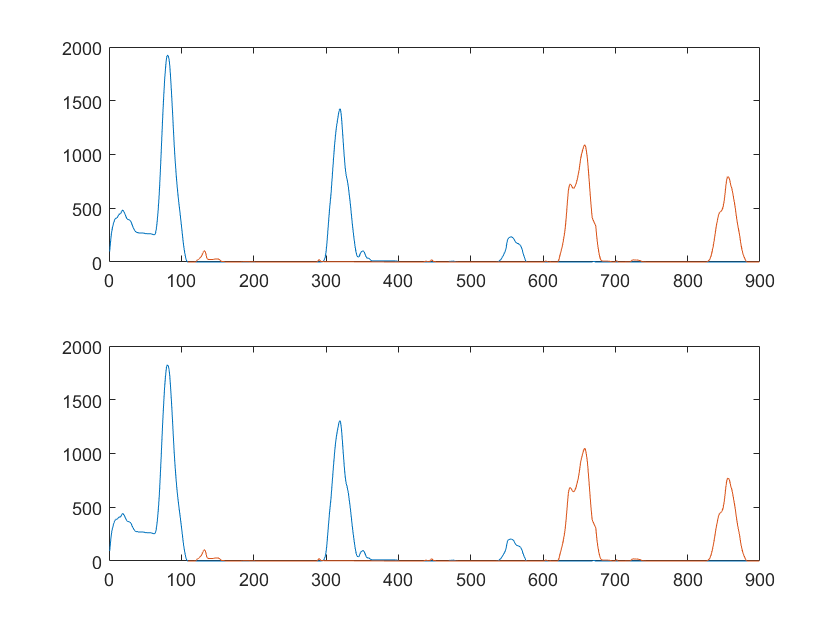

subplot(2,1,2)
plot(em{1,1}.ne{p,m});hold on
plot(find(em{2,1}.timefilter{p,m}),em{2,1}.ne{p,m});

Same starting time and K with lower M is not the major source of duplication...? 

2. limit range of k 

load('em_arena_th0.5.mat')
[N,nm]=size(em{1,1}.eve);
klist=[5,10,20,30,40];
ne_klist=cell(N,nm);
for r=1:2
for p=1:N
for m=1:2
[K,M,time]=limitk(klist,em{r,1}.K{p,m},em{r,1}.M{p,m},em{r,1}.time{p,m});
if r ==1 
    s=size(em{1,1}.ca_cl{p,m},2);
elseif r==2
    s=sum(em{2,1}.timefilter{p,m});
end
[ne_klist{p,m}]=count_eve(K,time,s);
end
end
em{r,1}.ne_klist=ne_klist;em{r,1}.klist=klist;
end

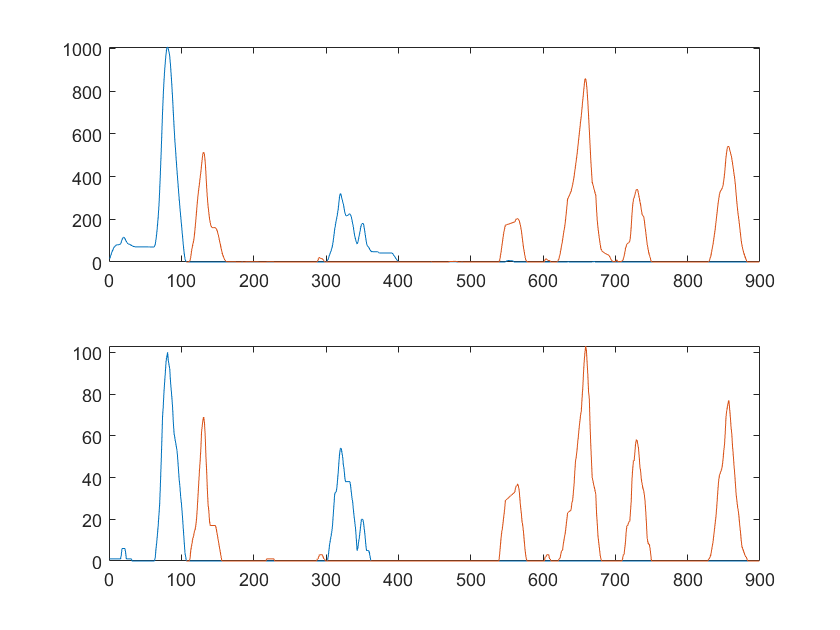

p=6;m=1;
subplot(2,1,1)
plot(em{1,1}.ne{p,m});hold on 
plot(find(em{2,1}.timefilter{p,m}),em{2,1}.ne{p,m});
subplot(2,1,2)
plot(em{1,1}.ne_klist{p,m});hold on
plot(find(em{2,1}.timefilter{p,m}),em{2,1}.ne_klist{p,m});